## **Linear Algebra Homework 2.**

**윤지상_ 미래자동차공학과 2019092115**

## **Exercise 1. **

### **Write the code that crates figure(Vector sum)**

**1-1. Visualization of v + w Vector**

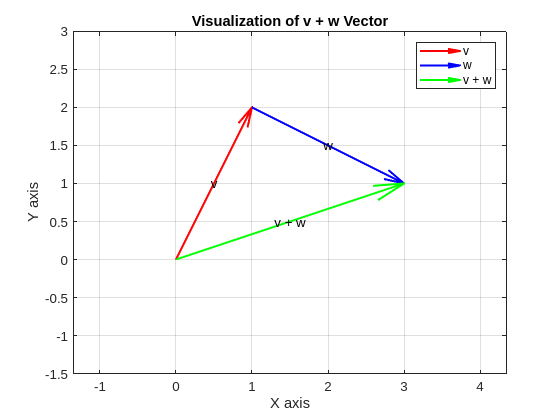

v = [1, 2];
w = [2, -1];
vPw = v + w;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v');
hold on;
quiver(v(1), v(2), w(1), w(2), 0, 'b', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='w');
quiver(0, 0, vPw(1), vPw(2), 0, 'g', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v + w');
hold off;

legend('show');
grid on;

xlabel('X axis');
xlim([-1.5, 4]);
ylabel('Y axis');
ylim([-1.5, 3]);
title('Visualization of v + w Vector');
axis equal;

text(v(1)/2, v(2)/2, "v",'HorizontalAlignment', 'center');
text(v(1)+w(1)/2, v(2)+w(2)/2, "w",'HorizontalAlignment', 'center');
text(vPw(1)/2, vPw(2)/2, "v + w",'HorizontalAlignment', 'center');

**1-2 Visualization of v - w Vector**

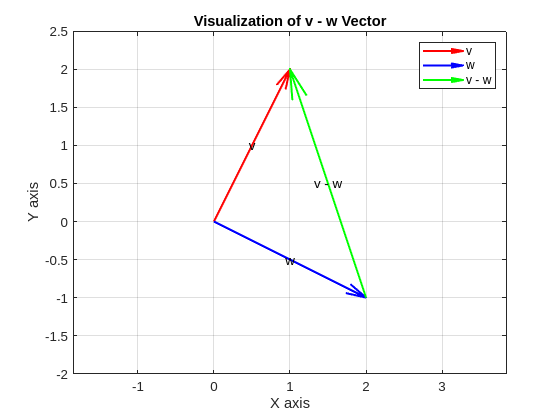

v = [1, 2];
w = [2, -1];
vMw = v - w;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v');
hold on;
quiver(0, 0, w(1), w(2), 0, 'b', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='w');
quiver(w(1), w(2), vMw(1), vMw(2), 0, 'g', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v - w');
hold off;

legend('show');
grid on;

xlabel('X axis');
xlim([-2, 3]);
ylabel('Y axis');
ylim([-2, 2.5]);
title('Visualization of v - w Vector');
axis equal;

text(v(1)/2, v(2)/2, "v",'HorizontalAlignment', 'center');
text(w(1)/2, w(2)/2, "w",'HorizontalAlignment', 'center');
text(w(1)+vMw(1)/2, w(2)+vMw(2)/2, "v - w",'HorizontalAlignment', 'center');

## Exercise 2. 

### Implement a function that takes a vector as input and outputs a unit vector in the same direction.

**Ex2 <Without template>**

clc;
clear;

%v = [2, 3];
v = input('Enter a vector [a b]: ');

function u = unitVec(vec)
    v_L2_norm = norm(vec, 2);
    disp(['Original vector L2 norm: ', num2str(v_L2_norm)]);
    u = vec / v_L2_norm;
end

u_v = unitVec(v); % made unit vector

Original vector L2 norm: 2.2361


disp(['Unit vector L2 norm: ', num2str(norm(u_v, 2))]);

Unit vector L2 norm: 1


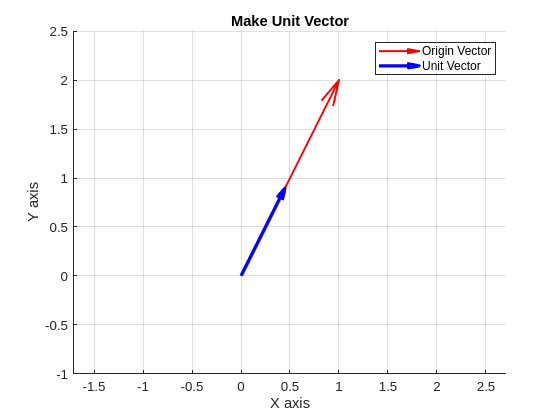


figure;
hold on;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='Origin Vector');
quiver(0, 0, u_v(1), u_v(2), 0, 'b', LineWidth=2.5, MaxHeadSize=0.4, DisplayName='Unit Vector');
hold off

legend('show');
grid on;

xlabel('X axis');
%xlim([-1, 4]);
xlim([-1, v(1)+0.5]);
ylabel('Y axis');
%ylim([-1, 4]);
ylim([-1, v(2)+0.5]);
title('Make Unit Vector');
axis equal;

**Ex2 <With template>**

% Test on a non-unit vector
w = [13; -5; 7];
uw = createUnitVectorWoNorm(w);
%  display w and uw var
disp(w);

    13
    -5
     7



disp(uw);

    0.8340
   -0.3208
    0.4491



disp(' ');

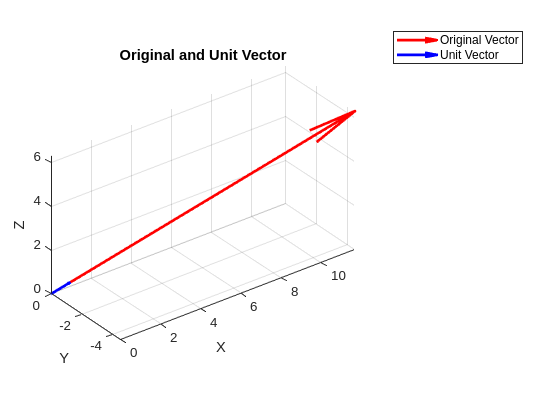


% Start plotting
figure;
quiver3(0, 0, 0, w(1), w(2), w(3), 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5); % Plot the original vector in red
hold on; % Hold on to plot the unit vector on the same graph
quiver3(0, 0, 0, uw(1), uw(2), uw(3), 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5); % Plot the unit vector in blue
axis equal; % Set the aspect ratio so that the scales are equal
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Original and Unit Vector');
legend('Original Vector', 'Unit Vector');
grid on; % Add a grid for better visibility



%%%%%%%%%%%%%%%% ToDo %%%%%%%%%%%%%%%%
function u = createUnitVectorWoNorm(v)
  % Manually calculate the norm of the vector
  mu = sqrt(sum(v.^2));
  % Avoid division by zero if the vector is all zeros
  if mu == 0
      u = 0;
  else
      % Return the unit vector
      u = v / mu;
  end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Exercise 3.

### Write the for loop that transposes row vector to column vector without using builtin fuction (e.g., A.T).

**<Without tempalte>**

clc;
clear;

%r_v = linspace(1, 10, 5);  % generate row vector
r_v = input('Enter a vector [a b c]: ');

% u_v = [];
% for i = 1:size(r_v, 2)
%     u_v = [u_v ; r_v(i)];
% end


function cv = columnVec(v)
    n = size(v, 2);
    cv = zeros(n,1);
    for i = 1:n
        cv(i) = v(i);
    end   
end

r_v

r_v =      2     3     4


c_v = columnVec(r_v);
c_v

c_v =      2
     3
     4


**Ex3 <With template>**

% matrix initializiation
mat_31 = [1;2;3];
mat_13 = [4,5,6];
mat_23 = [7,8,9;10,11,12];

% transpose 3x1 matrix
mat_31_transposed = manualTranspose(mat_31);
% transpose 1x3 matrix
mat_13_transposed = manualTranspose(mat_13);
% transpose 2x3 matrix
mat_23_transposed = manualTranspose(mat_23);

disp("Size of original matrix")

Size of original matrix


disp(size(mat_31));

     3     1



disp(size(mat_13));

     1     3



disp(size(mat_23));

     2     3




disp("Size of Transposed matrix")

Size of Transposed matrix


disp(size(mat_31_transposed));

     1     3



disp(size(mat_13_transposed));

     3     1



disp(size(mat_23_transposed));

     3     2



mat_23_transposed

mat_23_transposed =      7    10
     8    11
     9    12



%%%%%%%%%%%%%%%% ToDo %%%%%%%%%%%%%%%%
function vt = manualTranspose(v)
    % Get the size of the input matrix or vector
    [rows, cols] = size(v);
    
    % Initialize the transposed matrix with flipped dimensions
    vt = zeros(cols, rows);
    
    % Loop over the matrix to transpose it
    for i = 1:rows
        for j = 1:cols
            vt(j, i) = v(i, j);
        end
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%